Day 2 - Project Julia

## (h) & (i) Bonus

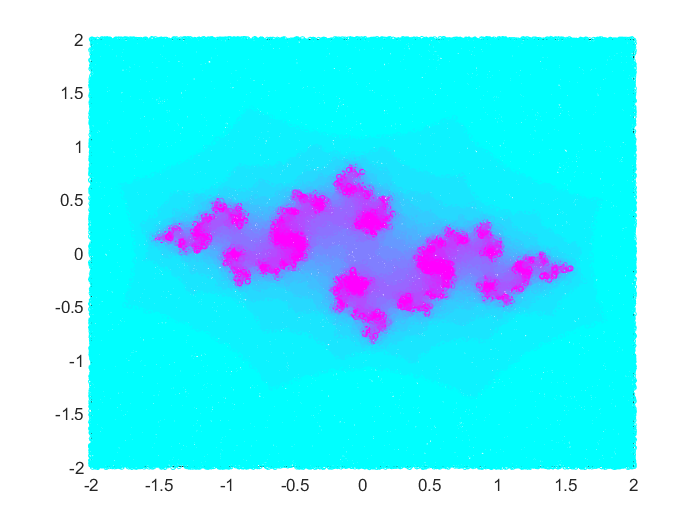

c = -0.836; d = exp(1)/10;
NSP = 1e5; % 1,000,000 Starting Points
a = -2; b = 2;
xStart = (b-a)*rand(NSP,1) + a; % vector of NSP random #s on [a,b]
yStart = (b-a)*rand(NSP,1) + a;
exitTime = zeros(1,NSP); % creating this now saves time later (o.w. exitTime keeps changing size)
for i = 1:NSP
    x = zeros(1,22); y = zeros(1,22); % creating these now saves comp run time later
    x(1) = xStart(i); y(1) = yStart(i);
    for n=1:21
        x(n+1) = x(n)^2 - y(n)^2 + c;
        y(n+1) = 2 * x(n) * y(n) + d;
        if abs(x(n+1)) > b || abs(y(n+1)) > b || n == 21
            exitTime(i) = n+1;
            break
        end
    end
end
figure; hold on; box on;
scatter(xStart,yStart,10,exitTime);
colormap cool;